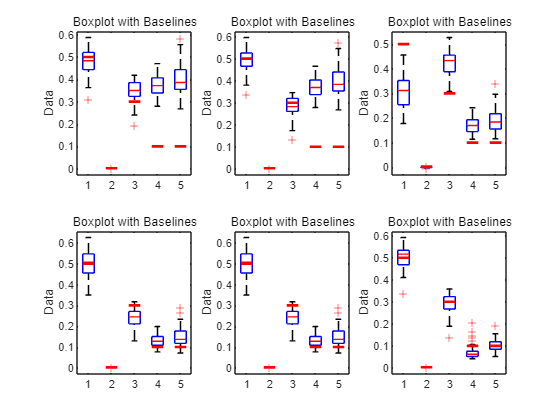

% Define the directory path where the .mat files are located
clear,clc
sde = 0;
nobs = 10;

for fileNumber = 1:50
    % Create the file name using the file number
    fileName = ['sde',num2str(sde),'inst',num2str(fileNumber-1),'nobs',num2str(nobs),'.mat'];
    %fileName = ['sde',num2str(sde),'inst',num2str(fileNumber-1),'nobs',num2str(nobs),'coarse_gp.mat'];

    % Create the full file path
    
    % Check if the file exists
    if exist(fileName, 'file')
        % Load the .mat file
        load(fileName)
        THETA_MAP(fileNumber,:) = theta_MAP;
        THETA_MAP_c(fileNumber,:) = theta_MAP_c;
        THETA_MAP_margin(fileNumber,:) = theta_MAP_margin;
        THETA_MAP_margin_c(fileNumber,:) = theta_MAP_margin_c;
        THETA_MLE(fileNumber,:) = theta_MLE;
        THETA_MLE_joint(fileNumber,:) = theta_MLE_joint;
    else
        fprintf('File not found: %s\n', fileName);
    end
end

figure
subplot(2,3,1)
box_for_multi_item(THETA_MAP, theta_true)
subplot(2,3,2)
box_for_multi_item(THETA_MAP_c, theta_true)
subplot(2,3,3)
box_for_multi_item(THETA_MAP_margin, theta_true)
subplot(2,3,4)
box_for_multi_item(THETA_MAP_margin_c, theta_true)
subplot(2,3,5)
box_for_multi_item(THETA_MLE, theta_true)
subplot(2,3,6)
box_for_multi_item(THETA_MLE_joint, theta_true)

# For result from cluster

% Define the directory path where the .mat files are located
clear,clc
sde = 2;
nobs = 100;
n_I = 100;
j = 1;
for fileNumber = 1:3000
    % Create the file name using the file number
    fileName = ['sde',num2str(sde),'inst',num2str(fileNumber-1),'nobs',num2str(nobs),'n_I',num2str(n_I),'new.mat'];
    %fileName = ['sde',num2str(sde),'inst',num2str(fileNumber-1),'nobs',num2str(nobs),'coarse_gp.mat'];

    % Create the full file path
    
    % Check if the file exists
    if exist(fileName, 'file')
        % Load the .mat file
        load(fileName)
        THETA_MAP(j,:) = theta_MAP;
        THETA_MAP_c(j,:) = theta_MAP_c;
        THETA_MAP_margin(j,:) = theta_MAP_margin;
        THETA_MAP_margin_c(j,:) = theta_MAP_margin_c;
        THETA_MLE(j,:) = theta_MLE;
        THETA_MLE_a(j,:) = theta_MLE_a;

        THETA_MLE_joint(j,:) = theta_MLE_joint;
        j = j+1;
    else
        %fprintf('File not found: %s\n', fileName);
    end
end
j

j = 61

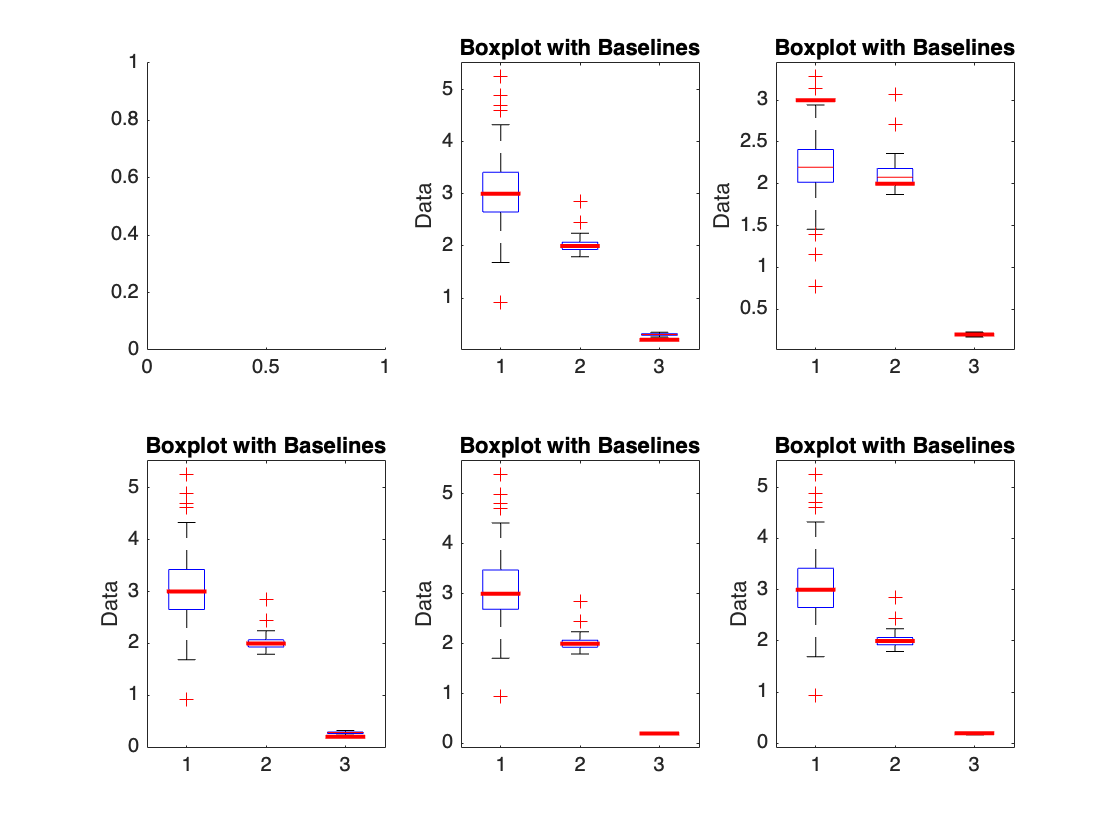


figure
subplot(2,3,1)
%box_for_multi_item(inferred_params(:,2:3), theta_true)
subplot(2,3,2)
box_for_multi_item(THETA_MAP_c, theta_true)
subplot(2,3,3)
box_for_multi_item(THETA_MAP_margin, theta_true)
subplot(2,3,4)
box_for_multi_item(THETA_MAP_margin_c, theta_true)
subplot(2,3,5)
box_for_multi_item(THETA_MLE_a, theta_true)
subplot(2,3,6)
box_for_multi_item(THETA_MLE_joint, theta_true)


clc
clear
load('mcmc_source0inst36nobs20n_I100mcmc.mat')

Error using load
Unable to find file or directory
'mcmc_source0inst36nobs20n_I100mcmc.mat'.

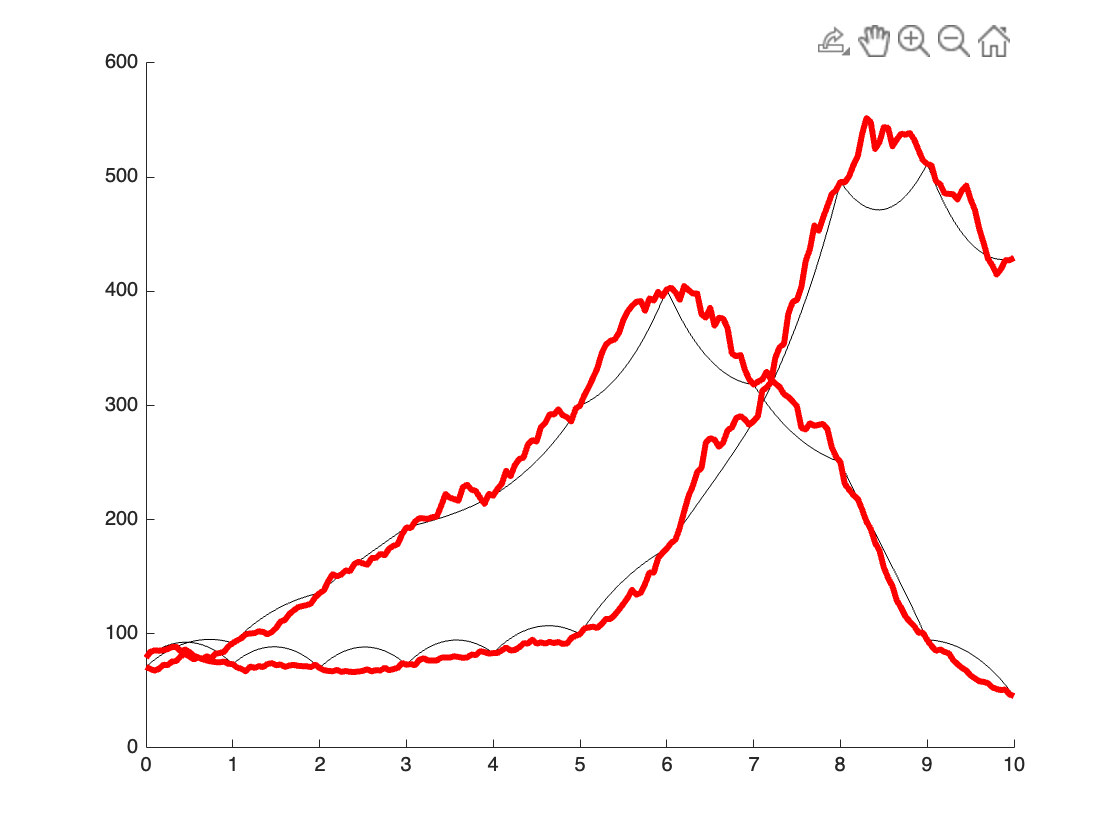


figure
hold on
for i =1:200
plot(t_true,sample_post_c(10*i+200,1:2:402),'k');
plot(t_true,sample_post_c(10*i+200,2:2:402),'k');

end
plot(t_true,x_true,'r-','LineWidth',3);

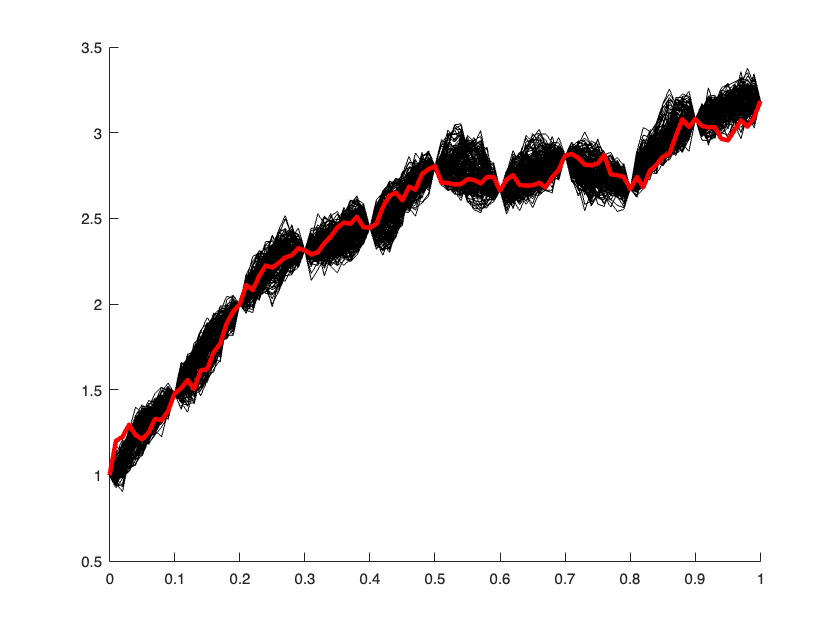

figure
hold on
for i =1:200
plot(t_true,sample_post_c(10*i+200,1:101),'k');

end
plot(t_true,x_true,'r-','LineWidth',3);

function box_for_multi_item(data, baseline)
    % Input validation
    assert(ismatrix(data), 'Data should be a matrix.');
    assert(isvector(baseline), 'Baseline should be a vector.');
    assert(size(data, 2) == numel(baseline), 'Number of columns in data should match the length of baseline.');

    % Create a boxplot
    boxplot(data);

    % Determine the number of items
    numItems = size(data, 2);

    % Add baselines for each item
    hold on;
    for i = 1:numItems
        line([i-0.25, i+0.25], [baseline(i), baseline(i)], 'Color', 'red', 'LineWidth', 2);
    end
    hold off;

    % Label the x-axis with item numbers
    xticklabels(1:numItems);

    % Label the y-axis
    ylabel('Data');
    
    % Add a title
    title('Boxplot with Baselines');
end




%% 


